# **drawNgon**

# **fillNgon**

Draw or fill a complete or partial 2D regular polygon.

## Description

## Syntax

drawNgon(n,r,xc,yc)

drawNgon(n,r,xc,yc,rot)

drawNgon(n,r,xc,yc,rot,v1,v2)

drawNgon(__,LineSpec)

p = drawNgon(__)

filldrawNgon(c,__)

### Description

drawNgon(n,r,xc,yc) draw ngon with center at given point. 

drawNgon(n,r,xc,yc,rot) draw ngon with center at given point and rotated by given angle. 

drawNgon(n,r,xc,yc,rot,v1,v2) draw part of ngon between vertices v1 and v2 in CCLW direction.

drawNgon(__,LineSpec)  sets the line style, marker symbol, and color.

drawNgon(__,pos) select between circumscribed and inscribed circle.

p = drawNgon(__) returns some output data.

### Method

For calculation of the coordinates of the ngon drawNgon call the function **evalNgon( n,r,xc,yc,rot,v1,v2)  **which returns coordinates *x *and *y *of the vertices v1 to v2 in CCW direction. If v1=v2 the poligon is closed. For usage of **evalNgon **see Example 1.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**c - **fill color

**n **- number of vertices

**r **- circumscribed (default) or inscribed circle radius. 

**xc - **x-coordinate of polygon center

**yc **- y-coordinate of polygon center

### **Optional Input Arguments**

**rot **- rotation angle about center in degrees

**pos **- defining circle position: '-in' or '-out' of polygon. If '-in' then the radius is for inscribed circleand is recalculated to radius of circumscribed circel* by * r/cosd(180/n)

** '-v',v1,v2**   -- start and end vertices in CCLW direction, 1<=v1,v2 <= n. It is not neccesary that v1 < v2 (see Example 2)

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with fields

- p.rr - radius of circumscribed circle

- p.r - radious of inscribed circle

- p.xc

- p.yc

- p.x - x-coordinates of the polygon (real column vector)

- p.y - y coordinates of the polygon (real column vector

- p.color - line color

*Note. *Polygon is closed so x(end) = x(1) and y(end) = y(1).

## Examples

### Example 1

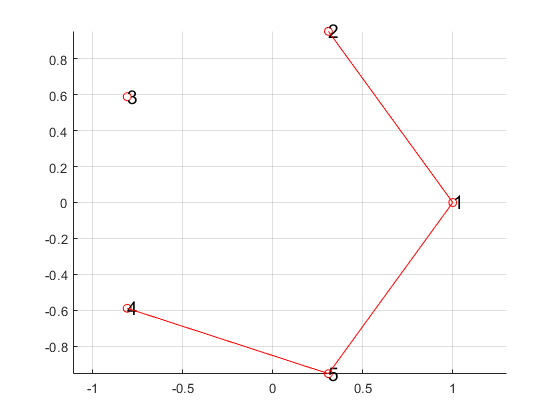

figure
hold on
axis equal
% Data
n = 5;
r = 1;
% close polygon
[xv,yv] = evalNgon( n, r, 0, 0, 0, 1, 1);
% plotvertices
scatter(xv,yv,'r')
for k = 1:n
    text(xv(k),yv(k),num2str(k),'FontSize',14)
end
% polyline between two vertices
v1 = 4;
v2 = 2;
[xv,yv] = evalNgon( n, r, 0, 0, 0, v1, v2);
% plot  polyline
plot(xv,yv,'r')
grid on

#### **Example 2**

figure
axis equal
hold on
% coordinates of polygon vertices
nv = 12; % number of vertices
% plot definiting polygon
p=drawNgon(nv,2,0,0,'r:')

p = struct with fields:
        r: 2
       rr: 2
        x: [2 1.7321 1 0 -1 -1.7321 -2 -1.7321 -1 0 1 1.7321 2 1.7321]
        y: [0 1 1.7321 2 1.7321 1 0 -1 -1.7321 -2 -1.7321 -1 0 1]
       xc: 0
       yc: 0
    color: [1 0 0]


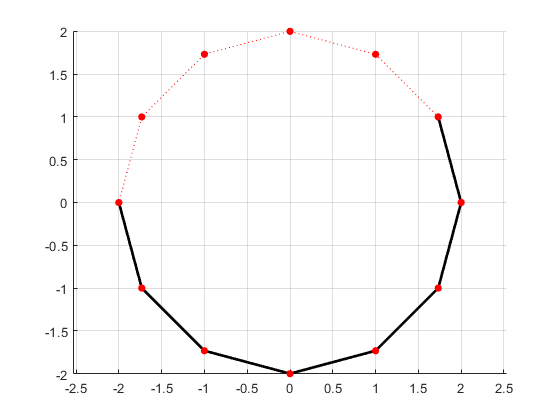

% Polyline between vertex 7 and 2
drawNgon(nv,2,0,0,'-v',7,2,'k','LineWidth',2);
% plot vertices
scatter(p.x,p.y,30,'r','filled')
grid on

#### **Example 3**

figure
axis equal
hold on
p=drawNgon(5,2,2,3,45)

p = struct with fields:
        r: 2
       rr: 2
        x: [3.4142 1.0920 0.0246 1.6871 3.7820 3.4142 1.0920]
        y: [4.4142 4.7820 2.6871 1.0246 2.0920 4.4142 4.7820]
       xc: 2
       yc: 3
    color: [0 0.4470 0.7410]


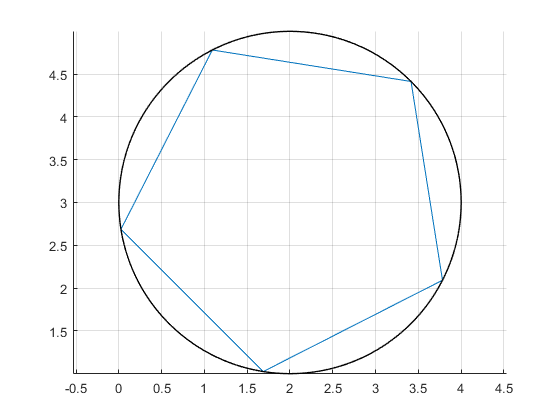

drawCircle(2,3,2)
drawCircle(p.xc,p.yc,p.rr)
grid on

### Example 4

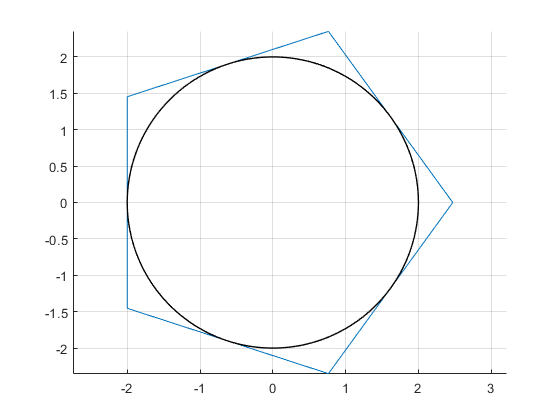

figure
axis equal
hold on
p=drawNgon(5,2,0,0,'-in');
drawCircle(p.xc,p.yc,2)
grid on

### Example 5

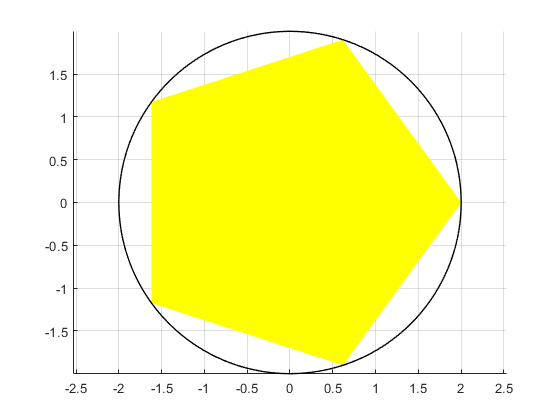

figure
axis equal
hold on
p=fillNgon('y',5,2,0,0,'-out');
drawCircle(p.xc,p.yc,2)
grid on

## See also

**drawCircle**

## References